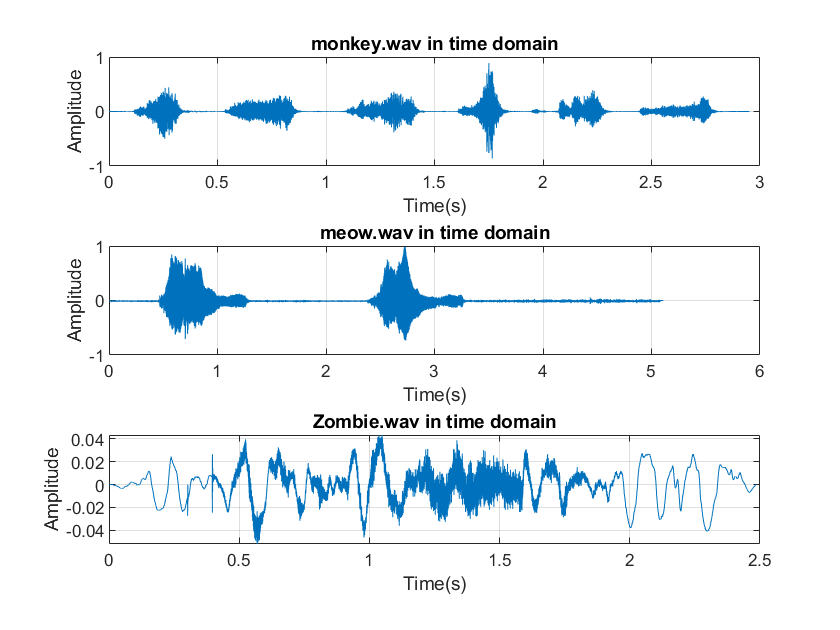



% Time domen of Audio signal

[x,Fs]=audioread('monkey.wav');

x=x(:,1);
dt1=1/Fs; %sampling interval
t1=0:dt1:(length(x)*dt1)-dt1; % time vector

subplot(3,1,1);
plot(t1,x);
xlabel('Time(s)');
ylabel('Amplitude');
title('monkey.wav in time domain')
grid on;


[y,Fs]=audioread('meow.wav');

y=y(:,1);
dt2=1/Fs;
t2=0:dt2 :(length(y)*dt2)-dt2;

subplot(3,1,2);
plot(t2,y); 
xlabel('Time(s)');
ylabel('Amplitude');
title('meow.wav in time domain')
grid on;

[z,Fs]= audioread('Zombie.wav ');

z=z(:,1);
dt3=1/Fs;
t3=0:dt3:(length(z)*dt3)-dt3;

subplot(3,1,3);
plot(t3,z); 
xlabel('Time(s)');
ylabel('Amplitude');
title('Zombie.wav in time domain')
grid on;

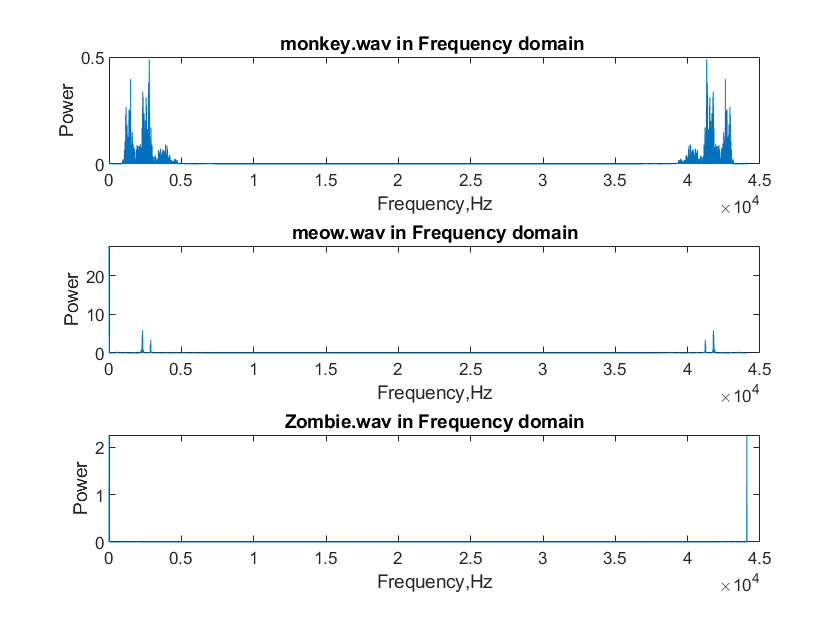


figure


%Frequency domain of Audio signal

%audio:-1
g = fft(x);
n = length(x);          % number of samples
f = (0:n-1)*(Fs/n);     % frequency range
b = abs(g).^2/n;    % power of the DFT
subplot(3,1,1);
plot(f,b);
xlabel('Frequency,Hz');
ylabel('Power');
title('monkey.wav in Frequency domain ');

%audio:-2
g = fft(y);
n = length(y);          % number of samples
f = (0:n-1)*(Fs/n);     % frequency range
b = abs(g).^2/n;    % power of the DFT
subplot(3,1,2);
plot(f,b);
xlabel('Frequency,Hz');
ylabel('Power');
title('meow.wav in Frequency domain');

%Audio:-3

k = fft(z);
n = length(z);          % number of samples
f = (0:n-1)*(Fs/n);     % frequency range
a = abs(k).^2/n;    % power of the DFT
subplot(3,1,3);
plot(f,a);
xlabel('Frequency,Hz');
ylabel('Power');
title('Zombie.wav in Frequency domain');

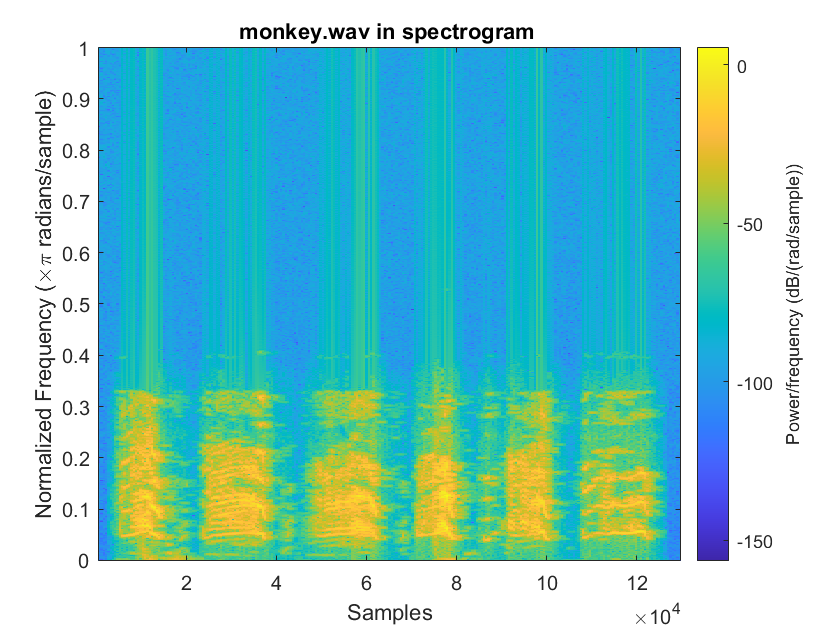


figure
%%spectrogram part
spectrogram(x,1024,512,1024,'yaxis')
title('monkey.wav in spectrogram ');

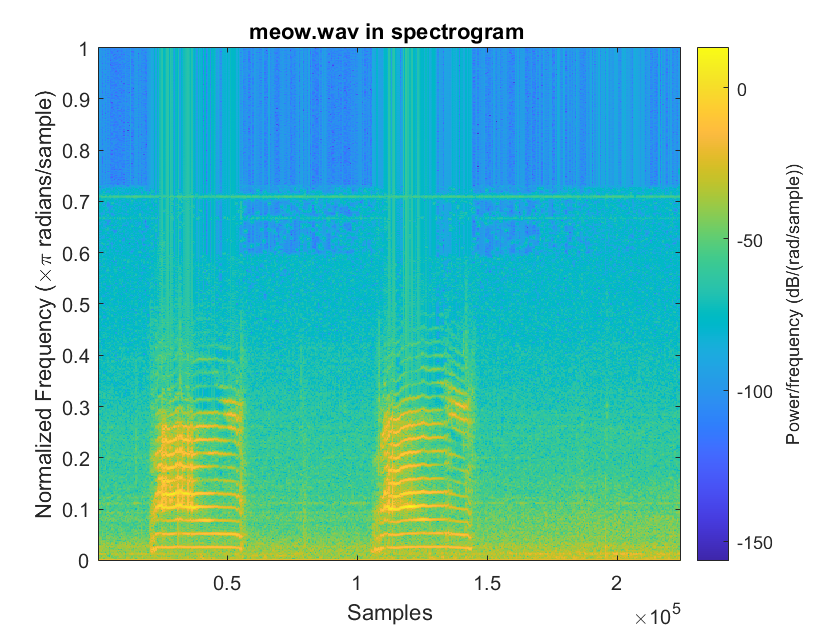


spectrogram(y,1024,512,1024,'yaxis')
title('meow.wav in spectrogram ');

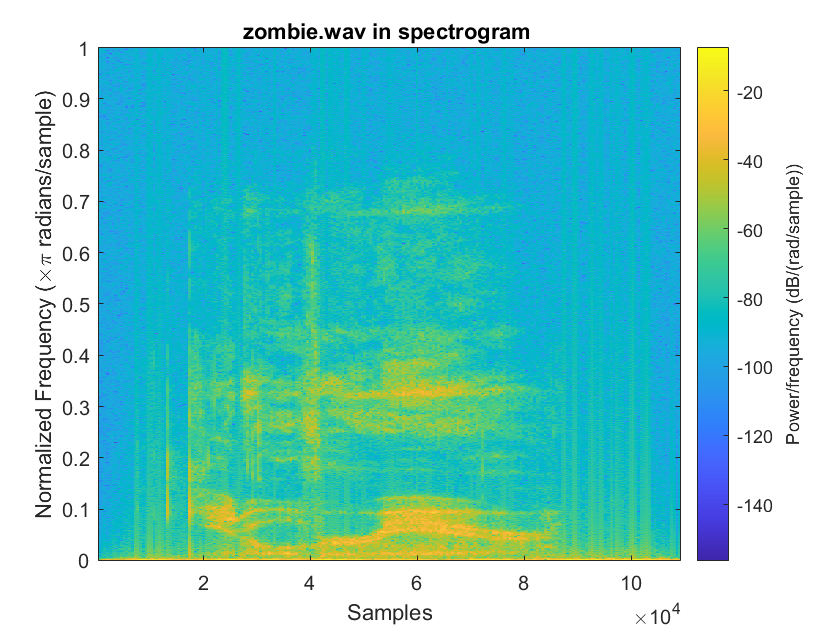


spectrogram(z,1024,512,1024,'yaxis')
title('zombie.wav in spectrogram ');

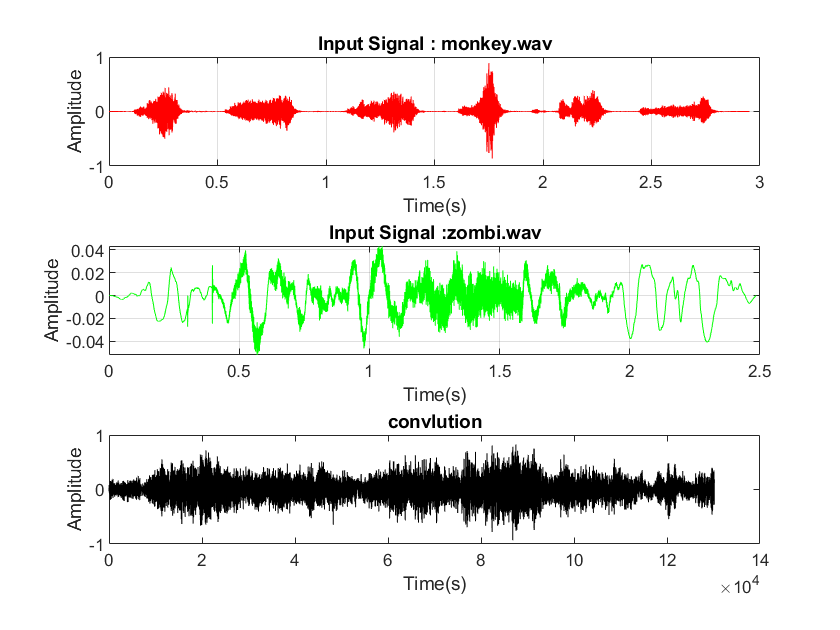







figure
%%Convolution  part


%plot the firt signal
subplot(3,1,1);
plot(t1,x,'r');
xlabel('Time(s)');
ylabel('Amplitude');
title('Input Signal : monkey.wav');
grid on;

%plot the audio signal
subplot(3,1,2);
plot(t3,z,'g');
xlabel('Time(s)');
ylabel('Amplitude');
title('Input Signal :zombi.wav');
grid on;

subplot(3,1,3);
op=conv2(x,z,'same');  %convlution 2 audio signal
plot(op,'k');    %plot 2 signal
title('convlution');
xlabel('Time(s)');
ylabel('Amplitude');